# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

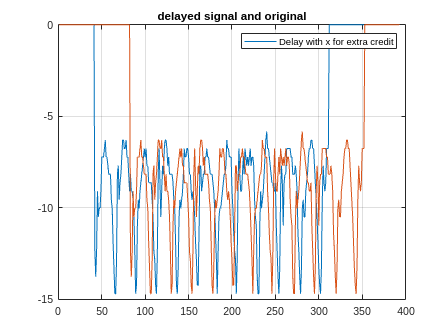

data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt');
% loading in the data from the csv matrix
converted_data = convert(data);
x = converted_data(:,1)';
y = converted_data(:,2)';
z = converted_data(:,3)';

a = x;
variance = [.01,.1, 1];
delay = 41;
ya = zeros(1,199);
x_a = [zeros(1,delay),a,zeros(1,delay)];
n = 1;
figure1 = figure();
plot(x_a)
hold on
grid on
alpha = .9;
noise = alpha.*sqrt(variance)'*randn(1,delay+length(x_a));
ya(delay+1:delay+length(x_a)) = x_a;
new_x = zeros(1,length(ya));
new_x(1:length(x_a)) = x_a;
x_a = new_x;
plot(ya)
title('delayed signal and original')
legend("Delay with x for extra credit")
hold off

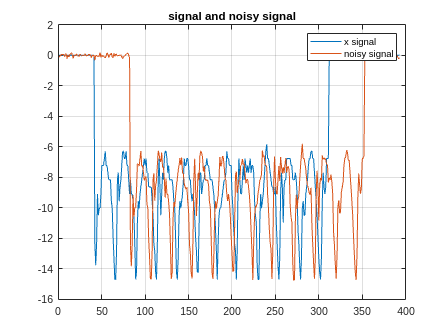

ya = ya + noise(n,:);
figure
plot(x_a)
hold on
plot(ya)
grid on
title('signal and noisy signal')
legend("x signal","noisy signal")
hold off


figure_delay = figure();
ryx = conv(ya,fliplr(x_a));
new_range = -floor(length(ryx)/2):1:floor(length(ryx)/2);
plot (new_range,ryx)
title(sprintf('Delay by correlation using \\sigma^2 = %2.2f',variance(n)))
hold on
ryx2 = conv(ya,fliplr(ya));
plot (new_range,ryx2);
[max_ryx, ryx_index] = max(ryx);
[max_ryx2, ryx2_index] = max(ryx2);
fprintf('colculated using maxes, delay = %3.3f',abs(ryx2_index - ryx_index))

colculated using maxes, delay = 41.000

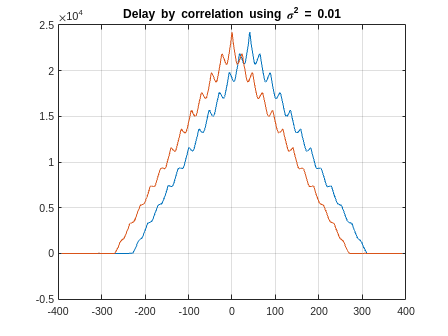

grid on
hold off

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end